# Week 1 — Bridge from Analog to Digital

**Discrete Signal Processing — Meeting 1**

clc; clear all; close all;
%
% By the end of this session you will be able to:
%
% * Explain what "discrete" and "digital" actually mean (they are not the
% same thing)
% * Sample a continuous-time signal correctly, and break it on purpose
% * Describe what happens inside an ADC (sample-and-hold + quantizer)
% * State the Nyquist theorem and *see* aliasing happen, not just recite
% it — in both the time domain and the frequency domain
%
% *How to use this script:* run each section with Ctrl+Enter. Sections
% marked *TRY THIS* have a variable at the top — change the number,
% re-run the section, and watch the plot change. That's the "interactive"
% part; feel free to also turn any of these into a slider via
% *Insert > Control > Slider* if you want the live-drag experience.

## 1. Discrete vs. Digital — they are not synonyms

A signal is **discrete-time** if it's only defined at separate time instants (a sequence of numbers), regardless of what values those numbers can take.

A signal is **digital** if, in addition, each of those numbers is rounded to one of a finite set of levels (because it lives in a finite number of bits).

So: discrete-time + continuous-valued = **sampled** signal (still exact values, just sampled in time). Add quantization on top of that, and **now** it's digital. This two-step story — sample, then quantize — is literally what an ADC does, and it's the whole plot of this lecture.

## 2. A real "analog" signal to work with

We don't have an actual analog world inside MATLAB, so we fake it with a very densely sampled signal and treat it as our stand-in for continuous time. This is standard practice and it's worth naming explicitly so it doesn't feel like a trick.

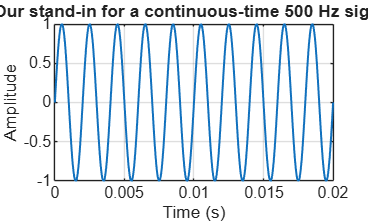

fs_analog = 100000;                 % "pretend continuous" — very high rate
t_analog  = 0:1/fs_analog:0.02;     % 20 ms window
f_signal  = 500;                    % 500 Hz tone — e.g. a mid-range audio tone
x_analog  = sin(2*pi*f_signal*t_analog);

plot(t_analog, x_analog, 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Amplitude');
title('Our stand-in for a continuous-time 500 Hz signal');
grid on;

## 3. Sampling it properly (fs comfortably above Nyquist)

**TRY THIS:** change `fs_sample` and re-run this section.

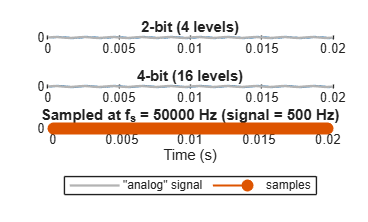

fs_sample = 50000;                   % sampling frequency, Hz
t_sample  = 0:1/fs_sample:0.02;
x_sample  = sin(2*pi*f_signal*t_sample);

plot(t_analog, x_analog, 'Color', [0.7 0.7 0.7]); hold on;
stem(t_sample, x_sample, 'filled', 'LineWidth', 1.2);
hold off;
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Sampled at f_s = %d Hz (signal = %d Hz)', fs_sample, f_signal));
legend('"analog" signal', 'samples', 'Location', 'southoutside', 'Orientation', 'horizontal');
grid on;


% Notice: with fs_sample = 5000 Hz and f_signal = 500 Hz, we're sampling
% 10x per cycle. Plenty of margin above Nyquist (2 x 500 = 1000 Hz
% minimum). The stems trace the sine shape faithfully.

## 4. Inside an ADC — sample-and-hold, then quantize

Real ADCs don't just pick instantaneous values; a sample-and-hold circuit grabs the voltage and holds it steady while the quantizer (a comparator ladder / successive-approximation / sigma-delta core, depending on the ADC architecture) decides which discrete level it's closest to.

We simulate the **quantizer** half here — that's the part that turns a sampled signal into a truly **digital** one.

**TRY THIS:** change `bits_to_show` and re-run — add or remove values to compare.

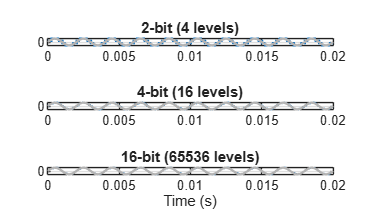

bits_to_show = [2, 4, 16];                    % ADC resolutions to compare

figure;
tiledlayout(numel(bits_to_show), 1);
for k = 1:numel(bits_to_show)
    n_bits = bits_to_show(k);
    levels = 2^n_bits;
    x_quant = round((x_sample + 1) * (levels-1) / 2) * (2/(levels-1)) - 1;

    nexttile;
    stairs(t_sample, x_quant, 'LineWidth', 1.4); hold on;
    plot(t_analog, x_analog, 'Color', [0.7 0.7 0.7]);
    hold off;
    title(sprintf('%d-bit (%d levels)', n_bits, levels));
    ylim([-1.2 1.2]);
end
xlabel('Time (s)');


% Read this top-to-bottom: at 2 bits the staircase is coarse and clearly
% visible against the gray "true" signal — lots of quantization error.
% By 8 bits the steps are so fine the staircase almost disappears into
% the true curve. More bits = more resolution = a closer match to the
% original. This is exactly why ADC resolution (bits) is a headline spec
% on every sensor/DAQ datasheet you'll touch as an engineer.

## 5. Nyquist theorem — and watching it fail on purpose

**Nyquist–Shannon:** to reconstruct a signal without ambiguity, you need fs > 2 x (highest frequency present in the signal).

Let's fix fs and sweep the signal frequency across that boundary instead — this is closer to how aliasing actually bites you in practice (a sensor or vibration that has more content than you planned for).

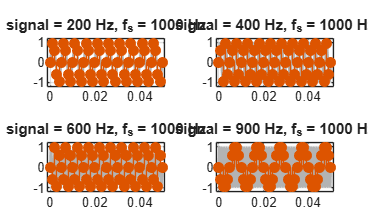

fs_fixed = 1000;                     % fixed sampling rate, Hz
freqs_to_test = [200, 400, 600, 900];  % Hz — note 600 and 900 exceed Nyquist (500 Hz)

t = 0:1/fs_fixed:0.05;
t_fine = 0:1/100000:0.05;

figure;
tiledlayout(2,2);
for k = 1:numel(freqs_to_test)
    f = freqs_to_test(k);
    x_true = sin(2*pi*f*t_fine);
    x_samp = sin(2*pi*f*t);

    nexttile;
    plot(t_fine, x_true, 'Color', [0.7 0.7 0.7]); hold on;
    stem(t, x_samp, 'filled');
    hold off;
    title(sprintf('signal = %d Hz, f_s = %d Hz', f, fs_fixed));
    ylim([-1.2 1.2]);
end


% Look closely at the 600 Hz and 900 Hz panels: the *samples themselves*
% trace out a slower sine wave that isn't there in the original signal.
% That slower fake wave is the alias. Nyquist limit here is fs/2 = 500 Hz
% — exactly where things start breaking.

## 5b. Proving it — the samples belong to a slower wave, in time

This is the payoff plot, redesigned to remove clutter. For any input frequency f sampled at fs, the frequency that will show up as a "fake" reconstructed signal is:

We deliberately DROP the true fast signal and the stem lines here — both were creating visual crossings that looked "mirrored." Instead: plain dots at the sample instants, and the slow alias curve computed independently. We also widen the time window so you can see several full cycles of the slow alias wave, not just a fraction of one.

**TRY THIS:** change `f_problem2` below (try any value above 500 Hz) and re-run — the dots will still land on the computed alias curve.

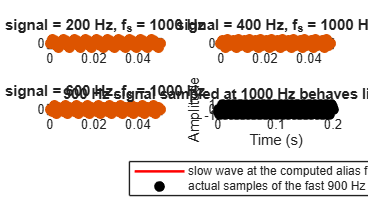

f_problem2 = 900;                    % Hz, > Nyquist (fs_fixed/2 = 500 Hz)
t_wide     = 0:1/fs_fixed:0.2;       % wider window: several alias cycles
t_wide_fine = 0:1/100000:0.2;

f_alias  = abs(f_problem2 - round(f_problem2/fs_fixed)*fs_fixed);
x_samp2  = sin(2*pi*f_problem2*t_wide);          % actual samples taken
x_ghost  = sin(2*pi*f_alias*t_wide_fine);        % slow curve, computed independently

plot(t_wide_fine, x_ghost, 'r-', 'LineWidth', 1.5); hold on;
plot(t_wide, x_samp2, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5);
hold off;
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('%d Hz signal sampled at %d Hz behaves like a %d Hz wave', ...
    f_problem2, fs_fixed, f_alias));
legend('slow wave at the computed alias frequency', ...
    'actual samples of the fast 900 Hz signal', ...
    'Location', 'southoutside', 'Orientation', 'vertical');
grid on;


% Every black dot sits exactly on the red curve — a curve that is NOT
% the 900 Hz signal we sampled, it's a much slower one we computed from
% the alias formula. There is no way to tell, from the samples alone,
% whether the source was really at 900 Hz or at f_alias. That ambiguity
% is the whole danger of aliasing, and it's a purely time-domain fact.

## 5c. The same aliasing, now seen in the frequency domain

Time domain shows WHAT happens (samples trace the wrong wave). Frequency domain shows WHERE the energy ends up — which is usually how you'll actually detect aliasing in real data, by seeing a peak show up somewhere it has no business being.

N = length(t_wide);
f_axis = (0:N-1)*(fs_fixed/N);          % frequency axis for fft(), 0..fs

X = abs(fft(x_samp2)) / N;

% Also compute the "clean" reference case for comparison: a signal that
% IS below Nyquist, sampled properly, so its peak lands where expected.
f_clean = 200;                           % Hz, well below fs_fixed/2 = 500 Hz
x_clean = sin(2*pi*f_clean*t_wide);
X_clean = abs(fft(x_clean)) / N;

tiledlayout(2,1);

nexttile;
stem(f_axis(1:N/2), 2*X_clean(1:N/2), 'filled');

xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title(sprintf('Properly sampled: %d Hz signal \\rightarrow peak AT %d Hz', f_clean, f_clean));
xline(fs_fixed/2, 'r--', 'Nyquist (f_s/2)');
grid on;

nexttile;
stem(f_axis(1:N/2), 2*X(1:N/2), 'filled');

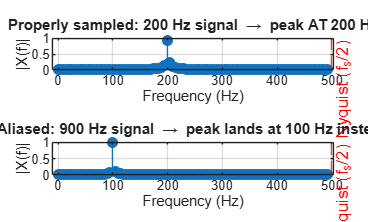

xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title(sprintf('Aliased: %d Hz signal \\rightarrow peak lands at %d Hz instead', f_problem2, f_alias));
xline(fs_fixed/2, 'r--', 'Nyquist (f_s/2)');
grid on;


% Top panel: input frequency and output peak match — this is what a
% "healthy" spectrum looks like. Bottom panel: we put in 900 Hz, but the
% spectrum shows a single clean peak at 100 Hz instead, with NOTHING at
% 900 Hz. The information about the true frequency is completely gone;
% it was folded down past Nyquist. This "folding" is exactly why the
% effect is called aliasing.

## 6. Wrap-up — connect it to what you'll touch as an engineer

- Every sensor/DAQ system you use (accelerometers, microphones, biosignal amplifiers, RF front-ends) has this exact chain: signal -> anti-aliasing filter -> ADC (sample-and-hold + quantizer) -> discrete, digital sequence.

- The number of ADC bits you choose trades resolution against noise floor and cost — same tradeoff whether it's a $2 microcontroller ADC or a $2000 lab digitizer.

- Sampling rate is not "faster is always better" — it's a design decision driven by the actual bandwidth of your signal, constrained by memory, power, and cost.

**Next meeting:** now that we have clean discrete sequences, we start operating on them directly — practical manipulations used in real signal pipelines.